**HRV spectral estimation **			

Load the signal ecg.mat (sampling frequency 360Hz), create a script (code and comments) to: 						

- analyze the signal in time and frequency domain

- detect the artefacts and filter them 

- study the function *peak_detection.m *, extract the tachogram and plot it (add the x-label and y-label)

- estimate the HRV using the most appropriate method (comment on your choice) 	

**1. analyze the signal in time and frequency domain**					

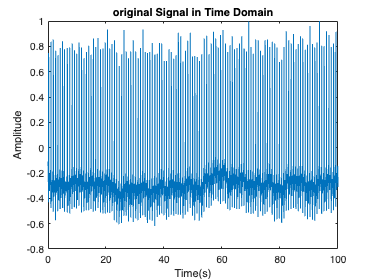

load ecg.mat;
fs = 360;
t=linspace(0,length(ecg)/fs,length(ecg));
figure()
plot(t,ecg/max(ecg));
title('original Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

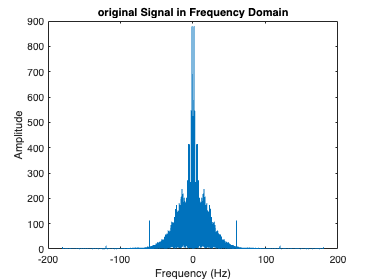


figure()
% ecg=ecg-mean(ecg); % Per visualizzare meglio lo spettro
f=linspace(-fs/2,fs/2,length(ecg));
plot(f,fftshift(abs(fft(ecg-mean(ecg)))));
title('original Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

analyzing the signal in the frequency domain, 

- it is visible a 60Hz interference. power line interference (artefatti da strumentazione) -> filtro stop band

- i have to remove the breathing artifact (low frequencies). rimuovo anche 0,5 Hz -> high pass

**2. detect the artefacts and filter them**

power line interference (artefatti da strumentazione) -> filtro stop band

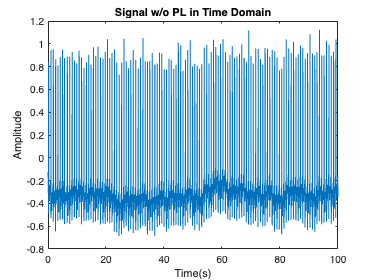

[b,a]=butter(4,[59,61]/(fs/2),'stop');
sig_f=filtfilt(b,a,ecg);
plot(t,sig_f)
title('Signal w/o PL in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

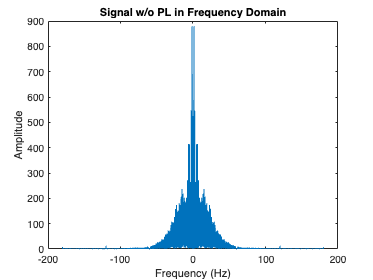


figure()
plot(f,fftshift(abs(fft(sig_f-mean(sig_f)))));
title('Signal w/o PL in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

 rimuovo anche 0,5 Hz -> high pass

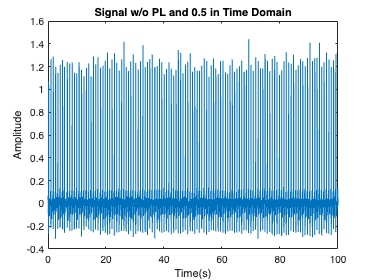


[b,a]=butter(4,[0.5]/(fs/2),'high');
sig_f1=filtfilt(b,a,sig_f);

plot(t,sig_f1)
title('Signal w/o PL and 0.5 in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

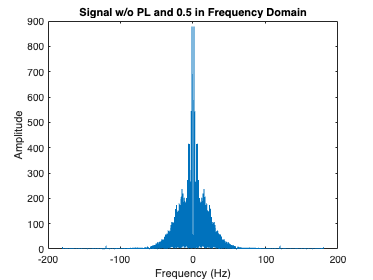


figure()
plot(f,fftshift(abs(fft(sig_f1))));
title('Signal w/o PL and 0.5 in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

# extraction of tachogram

#### 3. study the function peak_detection.m , extract the tachogram and plot it (add the x-label and y-label)

- Utilizzare la funzione `peak_detection` per rilevare i picchi nel segnale ECG filtrato.

- Calcolare gli intervalli tra i picchi R-R (R-R intervals).

- Creare il tachogramma, che è una rappresentazione degli intervalli R-R nel tempo.

- Plottare il tachogramma con le etichette sugli assi.

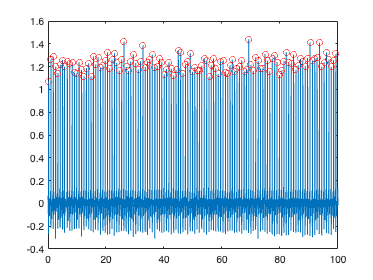

% Utilizza la funzione peak_detection per rilevare i picchi
threshold = 0.6 * max(sig_f1); % Soglia per rilevare i picchi al 60% del valore max
[R, N] = peak_detection(sig_f1, fs, threshold);

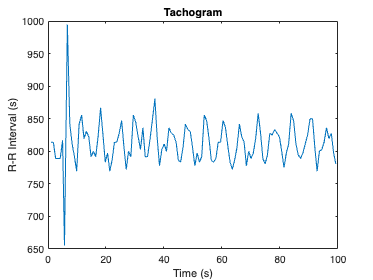


% Calcolo degli intervalli R-R (RR intervals)
RR_intervals = 1000* diff(R) / fs; % Gli intervalli R-R sono calcolati come le differenze tra gli indici dei picchi rilevati, convertiti in millisecondi.

% Creazione del vettore temporale per il tachogramma
t_tachogram = R(2:end) / fs; % Il vettore temporale per il tachogramma utilizza gli indici dei picchi R successivi, convertiti in secondi.

% Plot del tachogramma
figure();
plot(t_tachogram, RR_intervals);
title('Tachogram');
xlabel('Time (s)');
ylabel('R-R Interval (s)');

**4. estimate the HRV using the most appropriate method (comment on your choice) **

Per stimare la Variabilità della Frequenza Cardiaca (HRV), ci sono diversi metodi disponibili, tra cui l'analisi nel dominio del tempo, nel dominio della frequenza e metodi non lineari.

L'analisi nel dominio della frequenza è particolarmente utile perché permette di separare e analizzare le diverse componenti della variabilità della frequenza cardiaca, come le componenti a bassa frequenza (LF) e ad alta frequenza (HF), che sono indicative delle diverse influenze fisiologiche sul sistema cardiovascolare.

VLF(0-0.03 Hz)

LF (0.03-0.18 Hz)

HF (0.18-0.4 Hz) 

% To estimate Heart Rate Variability (HRV), various methods are available,
% including time-domain, frequency-domain, and nonlinear methods.
% Here, the frequency-domain analysis is chosen because it allows for the
% separation and detailed analysis of different components of heart rate variability,
% such as Low Frequency (LF) and High Frequency (HF) components.
% These components reflect different physiological influences on the cardiovascular system.
% 
% Frequency bands in HRV analysis
% VLF: Very Low Frequency, 0-0.03 Hz
% LF: Low Frequency, 0.03-0.18 Hz
% HF: High Frequency, 0.18-0.4 Hz

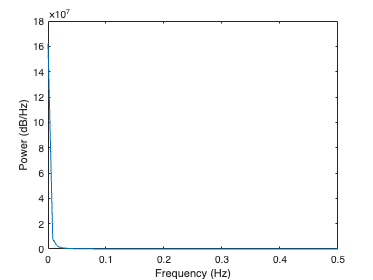


% Using the Yule-Walker method for power spectral estimation.
% The method is chosen for its efficiency in estimating power spectra from a relatively
% small set of data points, which is typical in HRV analysis.
[Pxx, fxx] = pyulear(RR_intervals, 5, length(RR_intervals), 1); % Order of 5 for AR model

% Plotting the power spectrum
figure();
plot(fxx, Pxx);
ylabel('Power (dB/Hz)'); 
xlabel('Frequency (Hz)');

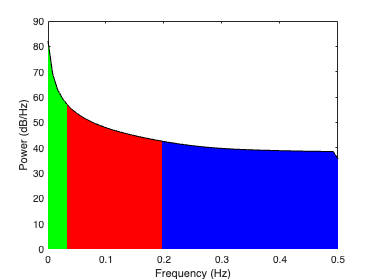


% Plotting the power spectrum
figure();
plot(fxx, 10*log10(Pxx)); % Convert power to dB/Hz for better visualization
ylabel('Power (dB/Hz)'); 
xlabel('Frequency (Hz)');


% Highlighting the frequency bands in the plot with different areas
hold on; % Retain the current plot when adding new plots
area(fxx, 10*log10(Pxx), 'FaceColor', 'b'); % Entire spectrum area
area(fxx(1:25), 10*log10(Pxx(1:25)), 'FaceColor', 'r'); % Low Frequency area
area(fxx(1:5), 10*log10(Pxx(1:5)), 'FaceColor', 'g'); % Very Low Frequency area




% Colors are used to distinguish between the different frequency bands:
% - Blue for the entire spectrum
% - Red for LF
% - Green for VLF
